# Global Temperature

[⇦ Overview](matlab: OpenOverview)

**Learning Goals**

- Load time-series temperature data into MATLAB.

- Compare regional temperature trends using time-series plots.

- Apply array indexing to compute changes to CO$_2$ concentration.

- Discuss correlation and autocorrelation of climate time-series data.

## 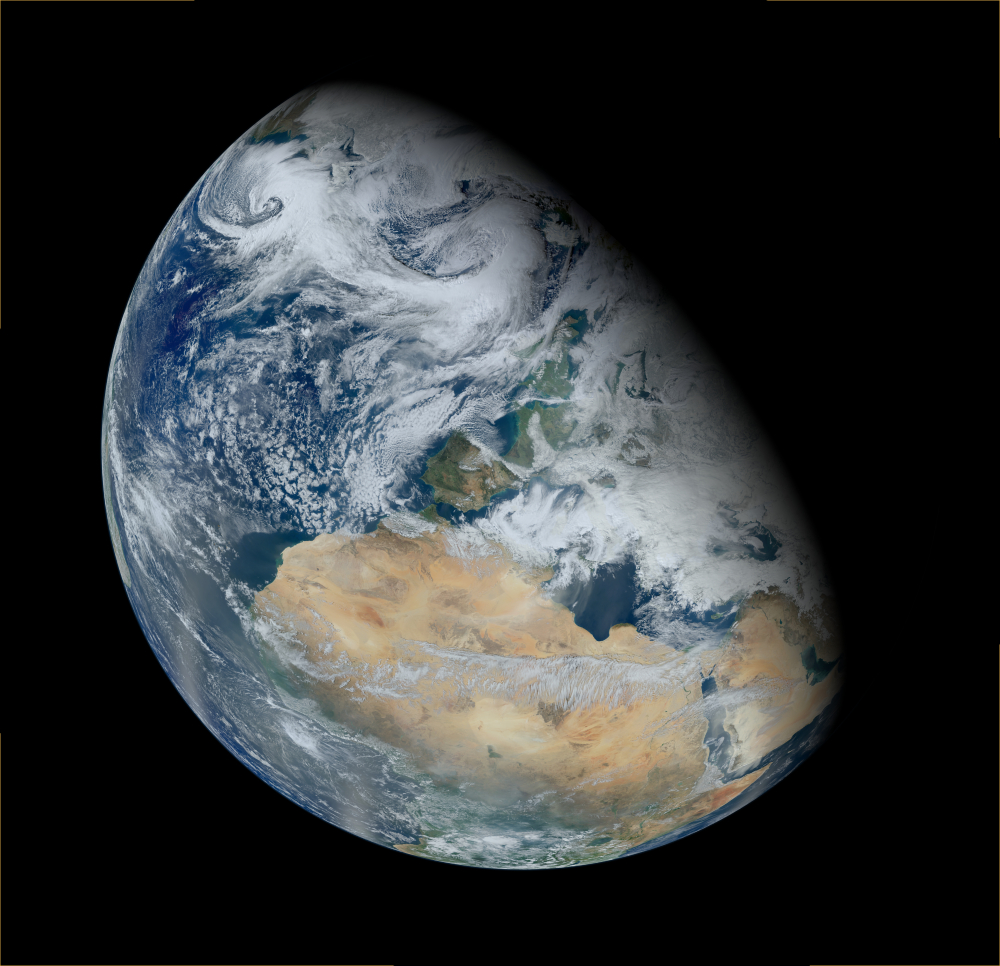

*View of the Earth synthesized from Suomi NPP satellite data. Image courtesy of NASA's Visible Earth collection *[1]*.*

As greenhouse gases continue to be released into the atmosphere, temperatures rise across the globe. To better understand the extent of these changes, you can analyze historical data. In this live script, you will plot and analyze time-series temperature data and greenhouse gas concentration data. 

 Make sure the project is loaded so that the data files are available on the MATLAB Path. To load the project, double-click the project PRJ file (`ClimateVis.prj`) in the Current Folder browser.

## A Warming Planet

In the basic theory of climate change, increases in atmospheric greenhouse gas concentrations cause the Earth to retain additional heat, leading to a rise in global temperature. In this section, you will plot temperature anomaly data aggregated from the Global Historical Climatology Network (GHCN) [2] and the International Comprehensive Ocean-Atmosphere Data Set (ICOADS) [3]. You can preview and download the data from the National Centers for Environmental Information (NCEI) website [here](https://www.ncdc.noaa.gov/cag/global/time-series) [4]. 

Time series data is often contained in tables, where each new row of the table represents a new data point. The global anomaly temperature data is contained in a CSV (comma-separated values) file: [`GlobalTempAnomaly.csv`](matlab: edit("GlobalTempAnomaly.csv")). This data is formatted as a table, with the columns separated by commas.

   **Activity.** Review the global time-series data.

**Task 1.** Review the tabular global temperature data: [`GlobalTempAnomaly.csv`](matlab: edit("GlobalTempAnomaly.csv")). What units are used (°F/°C)?

**Task 2. **Run this section to load and plot the yearly global temperature anomaly. To run the section, click the blue bar on the left

      

or click   **Run Section** from the **Section** pane of the **Live Editor **tab.

% Read the data
DataGbl = readtable("GlobalTempAnomaly.csv"); 
% Extract the year and anomaly columns
YearGbl = DataGbl.Year; 
AnomalyGbl = DataGbl.Value; 

% Create the plot
plot(YearGbl,AnomalyGbl) 
title("Annual Global Temperature Anomaly")
ylabel("Anomaly (°C)")
xlabel("Year")

**  Reflect.** The data plotted in this section does not show the global temperature averages. Instead, it shows the global temperature anomaly: the difference between yearly average global temperatures and a reference temperature.

- What reference temperature is used? You can find out by reviewing the [data information](https://www.ncdc.noaa.gov/cag/global/data-info) on the NCEI website.

- Why does the NCEI publish the data as temperature anomaly instead of global temperature averages?

## Regional Temperature Anomalies

The global temperature anomaly plotted in the last section incorporates both land and ocean temperatures. While global characteristics are important for understanding global impact, local effects could vary. Reviewing regional temperature time-series data can help to illustrate how strongly a particular region is impacted.

   **Activity.** In this activity, you will plot continental temperature anomalies and compare them to the global anomaly.

**Task 1. **Run this section to plot the global and North American temperature anomalies together.

%% Tasks 1 & 2 Solution
% Read the data
DataNA = readtable("NATempAnomaly.csv"); 
% Extract the year and anomaly columns
YearNA = DataNA.Year; 
AnomalyNA = DataNA.Value;

% EU data
DataEU = readtable("EUTempAnomaly.csv");
YearEU = DataEU.Year;
AnomalyEU = DataEU.Value;

% Create the plot
plot(YearGbl,AnomalyGbl)
hold on % Continue to plot on the same axes
plot(YearNA,AnomalyNA) 
plot(YearEU,AnomalyEU) 
hold off 
title("Annual Temperature Anomaly")
ylabel("Anomaly (°C)")
xlabel("Year")
legend("Global","North America","Europe","Location","northwest")

**Task 2. **Data is also available for Europe. Modify the code above so that the European temperature anomalies are also plotted. Using the existing code to read and plot the North American data as a reference, perform the following:

- Add another call to the [`readtable`](https://www.mathworks.com/help/matlab/ref/readtable.html) function to read the data from `EUTempAnomaly.csv`. Store the result in DataEU.

- Extract the year and anomaly from the table DataEU using the dot notation (e.g., DataEU`.year`). Store the results in YearEU and AnomalyEU.

- Add another call to [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html) between the `hold on` and `hold off` commands to plot the EU data: AnomalyEU vs YearEU.

- Add a third entry to the legend after "North America" (but before "Location") called "Europe".

When you have finished modifying the code, run the section. If correct, you should see the European temperature anomaly plotted alongside the others.

There's a great deal of yearly variation in the continental temperature anomalies, so it's difficult to see if they are trending higher or lower than the global anomaly. To make it easier to see the long-term trends, you can compute a moving average of the data using the function [`movmean`](https://www.mathworks.com/help/matlab/ref/movmean.html). This function averages data points within a moving window. 

**Task 3. **Run this section to plot the yearly global temperature anomaly with a 10-year moving average.

% Compute the moving mean
mmAnomalyGbl = movmean(AnomalyGbl,10);

% Create the plot
plot(YearGbl,mmAnomalyGbl) 
title("Temperature Anomaly (10-year moving average)")
ylabel("Anomaly (°C)")
xlabel("Year")

   **Activity.** In this activity, you will compute and plot the moving average for the other two data sets.

**Task 1. **Compute the 10-year moving average of the temperature anomaly data for North America and Europe using the [`movmean`](https://www.mathworks.com/help/matlab/ref/movmean.html) function. The data sets are stored in AnomalyNA and AnomalyEU. Store the result in `mmAnomalyNA `and `mmAnomalyEU`. Use the syntax

where `k` is the number of points to include in the sliding window. Use `k = 10` to compute the 10-year moving average.

% Write your code here
mmAnomalyNA = movmean(AnomalyNA,10);
mmAnomalyEU = movmean(AnomalyEU,10);

**Task 2. **The code below plots the 10-year global moving average. Modify the code so that the NA and EU data are also plotted.

- Use [`hold on`](https://www.mathworks.com/help/matlab/ref/hold.html) to continue plotting on the same axes.

- Plot the moving mean anomalies against the corresponding temporal data: `mmAnomalyNA` against YearNA and `mmAnomalyEU` against YearEU. Use the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html) command.

- Use the `hold off` command to stop plotting on the same axes.

- Add a [`legend`](https://www.mathworks.com/help/matlab/ref/legend.html). You can copy this from the previous example.

% % Solution to Task 2

plot(YearGbl,mmAnomalyGbl) 
% Add your code here
hold on
plot(YearNA,mmAnomalyNA)
plot(YearEU,mmAnomalyEU)
hold off

title("Temperature Anomaly (10-year moving average)")
ylabel("Anomaly (°C)")
xlabel("Year")
legend("Global","North America","Europe","Location","northwest")

## Greenhouse Gases

The plots from the previous section illustrate global temperature anomalies, with increases of over 1.5 °C in the continents of North America and Europe over the last 40 years. The basic theory of climate change attributes the rising temperatures to anthropogenic greenhouse gas emissions, i.e., emissions resulting from human activity. 

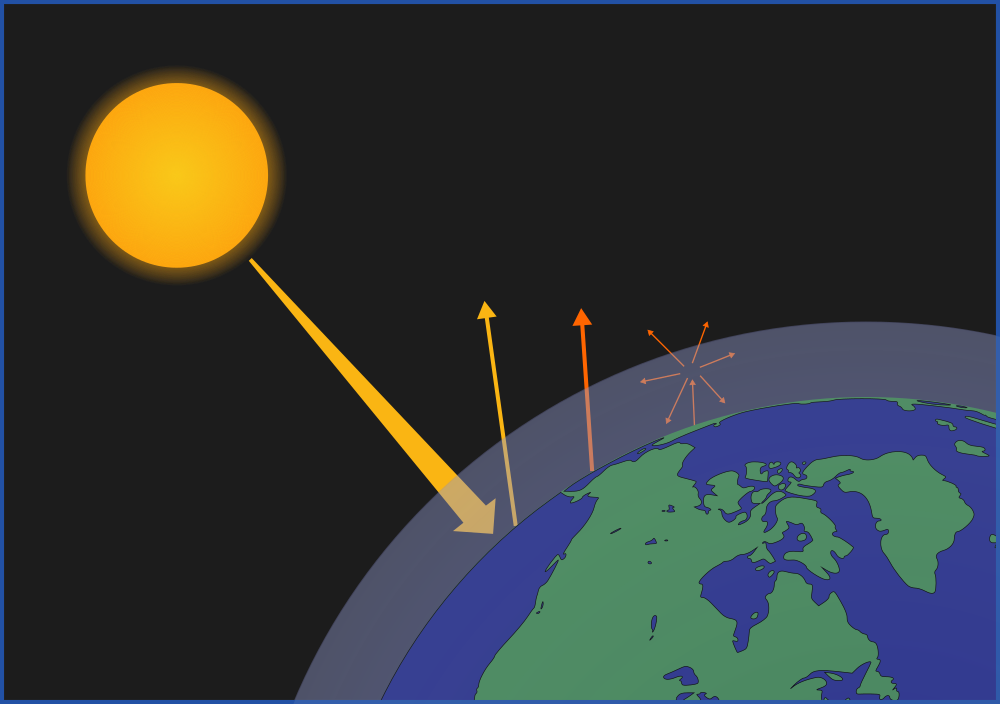

*Illustration of solar radiation and reflection. Radiation leaves the Earth as reflected light or blackbody radiation. Greenhouse gases, such as carbon dioxide (CO*$_2$)*, absorb and reemit radiation before it leaves the atmosphere, leading to additional heat being retained.*

The most abundant greenhouse gas is carbon dioxide (CO$_2$), followed by methane (CH$_4$). To understand how much CO$_2$ has been released into and retained by the atmosphere, you can examine CO$_2$ concentration time-series data from the Mauna Loa observatory in Hawaii [5]. This data is freely available and can be downloaded from the NOAA Global Monitoring Laboratory website [here](https://gml.noaa.gov/ccgg/trends/data.html).

   **Activity.** In this activity, you will read Mauna Loa CO$_2$ data [5].

**Task 1. **Use the [`readtable`](https://www.mathworks.com/help/matlab/ref/readtable.html) function to read the Mauna Loa CO$_2$ data contained in `MaunaLoaCO2.csv` into a variable named DataCO2. Use the syntax

to read the data. Forego the usual end-of-line semicolon so you can review the data table.

% Write your code here
DataCO2 = readtable("MaunaLoaCO2.csv")

**Task 2**. Examine the table loaded in the previous activity. Notice that the first column shows the years over which the recording was taken. Extract this column using the dot notation: T`.col`, where `T` is the table and `col` is the column you want to extract. Store the result in a variable named YearCO2.

% Write your code here
YearCO2 = DataCO2.year;

**Task 3. **Extract the `mean` column from the data table. This column records the mean measured CO$_2$ in parts per million (ppm). Store the result in a variable called MeanCO2.

MeanCO2 = DataCO2.mean;

**Task 4.** Plot MeanCO2 against YearCO2 using [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html). Also label the y-axis as "CO_2 (ppm)" and the x-axis as "year" using the [`xlabel`](https://www.mathworks.com/help/matlab/ref/xlabel.html) and [`ylabel`](https://www.mathworks.com/help/matlab/ref/ylabel.html) functions.

plot(YearCO2,MeanCO2)
ylabel("CO_2 (ppm)")
xlabel("year")

**Task 5. **By what percentage did the global CO$_2$ increase between 1959 and 2021? Compute the percent increase as 


$$\text{\% Increase}= \frac{\text{Final value} - \text{Initial value}}{|\text{Initial value}|} \cdot 100\%$$


To calculate this, you need to use the first and last value of the MeanCO2 vector. You can access the first element of the vector by indexing: MeanCO2`(1)`. To access the last value, use MeanCO2`(end)`. Store your answer in a variable called PercI`ncreaseCO2`. 

PercIncreaseCO2 = (MeanCO2(end) - MeanCO2(1))/MeanCO2(1)*100

 **Exercise. **The second most abundant greenhouse gas is methane. The global mean methane data is available freely from the Global Monitoring Laboratory [6]. The data is stored in `MethaneData.txt,` where the mean data is given in parts per billion (ppb). This data is in a tabular format, so it can be read using readtable. Perform the following. 

- Read the methane data from `MethaneData.txt`. Store the year in a variable called YearC`H4` and the mean methane values in MeanC`H4`. You will use these variables in a following activity. 

- Plot the time series.

- Compute the percent increase in methane between 1984 and 2020. Store your answer in PercI`ncreaseCH4`.

% Write your code here
DataCH4 = readtable("MethaneData.txt");
MeanCH4 = DataCH4.mean;
YearCH4 = DataCH4.year;
plot(YearCH4,MeanCH4)
xlabel("Year")
ylabel("CH_4 (ppb)")
PercIncreaseCH4 = (MeanCH4(end)-MeanCH4(1))/MeanCH4(1)*100

**  Reflect.** 

- Because the CH$_4$ and CO$_2$ data were recorded over different time spans, it's difficult to tell which has increased faster (percentage-wise). Compute the average yearly percentage increase. To do so, divide the percent increase of the gas by the time span over which the increase occurred. Which greenhouse gas is increasing more quickly?

PercIncreaseCH4/range(YearCH4)
PercIncreaseCO2/range(YearCO2)

- Based on the data you've analyzed so far, can you tell which greenhouse gas (CH$_4$ or CO$_2$) contributes more to global temperature increase? What other data might be required to make an assessment?

## Data Correlation

The data indicates that global temperatures and greenhouse gas concentrations have risen over the last four decades. How closely do those increases relate to each other? One of the simplest analyses to relate two sets of data is to compute their correlation. The Pearson correlation coefficient, $r$, quantifies how linearly related the two data sets are. The correlation $r$ will approach 1 when the data is highly correlated, 0 if the data is uncorrelated, and -1 if the data is anti-correlated. 

   **Activity. **In this activity, you will analyze correlations in the climate data. Note that for this activity to work, you must have correctly completed the previous activities.

**Task 1. **Run this section to compute the correlation between the global temperature anomaly and Mauna Loa CO$_2$ measurements using the [`corrcoef`](https://www.mathworks.com/help/matlab/ref/corrcoef.html) function.

% Extract the years of the temperature data
% that match the years in the CO2 data
IdxStart = find(YearGbl == YearCO2(1));
IdxEnd = find(YearGbl == YearCO2(end));
AnomalyMatchCO2 = AnomalyGbl(IdxStart:IdxEnd);

% Compute the correlation coefficient
R = corrcoef(AnomalyMatchCO2,MeanCO2)

**Task 2. **Notice that there are four values, but two are redundant. The diagonals show the correlation of each vector with itself (which is always 1). The off-diagonals show the correlation between the two vectors: the temperature anomaly and the CO$_2$ concentration. What is the value of the correlation between the temperature anomaly and CO$_2$ concentration? Store your result in CorrC`O2`.

**Hint: **You can extract an element of a matrix $M$ with row $i$ and column $j$ using the syntax:

CorrCO2 = R(1,2)

**Task 3. **The correlation coefficient suggests that the CO$_2$ and temperature anomaly data are highly correlated (since the $r$-value is close to 1). However, there are potential issues with using the Pearson correlation coefficient on time-series data. If the time-series data is correlated to its own time history (known as autocorrelation), then a bias is introduced. 

Run this section to compute the autocorrelation of the CO$_2$ data. Each value of the autocorrelation represents how correlated the CO$_2$ data is with itself `lag` years prior. The correlation is plotted on the $y$-axis, and the lag on the $x$-axis.

[lag,acorr] = AutoCorrelation(MeanCO2); % Helper function that compute the autocorrelation
stem(lag,acorr)
xlabel("Lag (years)")
ylabel("Autocorrelation")

**  Reflect.** 

- What is the autocorrelation coefficient of the data with itself five years prior?

- Is the CO$_2$ data strongly autocorrelated?

[⇦ Overview](matlab: OpenOverview)

## References

[1] Image by Norman Kuring, NASA GSFC, using data from the VIIRS instrument aboard Suomi NPP. Accessed 1 March, 2022 from [https://visibleearth.nasa.gov/images/78314/north-africa-and-europe-from-suomi-npp](https://visibleearth.nasa.gov/images/78314/north-africa-and-europe-from-suomi-npp).

[2] Jay H. Lawrimore, Matthew J. Menne, Byron E. Gleason, Claude N. Williams, David B. Wuertz, Russell S. Vose, and Jared Rennie (2011): Global Historical Climatology Network - Monthly (GHCN-M), Version 3. NOAA National Centers for Environmental Information. doi:10.7289/V5X34VDR. Accessed 1 March, 2022.

[3] Freeman, E., Woodruff, S.D., Worley, S.J., Lubker, S.J., Kent, E.C., Angel, W.E., Berry, D.I., Brohan, P., Eastman, R., Gates, L. and Gloeden, W., 2017. ICOADS Release 3.0: a major update to the historical marine climate record. *International Journal of Climatology*, *37*(5), pp.2211-2232.

[4] Climate at a Glance, NOAA National Center for Environmental Information (NCEI), Accessed 2 March, 2022 from [https://www.ncdc.noaa.gov/cag/global/time-series](https://www.ncdc.noaa.gov/cag/global/time-series).

[5] Data provided by Dr. Pieter Tans, NOAA/GML (gml.noaa.gov/ccgg/trends/) and Dr. Ralph Keeling, Scripps Institution of Oceanography (scrippsco2.ucsd.edu/). Mauna Loa CO2 annual mean data. NOAA Global Monitoring Laboratory. Accessed 2 March, 2022.

[6] Data provided by *Ed Dlugokencky, NOAA/GML (gml.noaa.gov/ccgg/trends_ch4/)*. Global CH4 Monthly Means. NOAA Global Monitoring Laboratory. Accessed 2 March, 2022.

**Helper Functions**

function [lag,acorr] = AutoCorrelation(x)
    % Estimates the autocorrelation using a simple discretization
    meanx = mean(x);
    n = numel(x);
    varx = 1/n*sum((x - meanx).^2);
    acorr = zeros(n,1);
    lag = 0:(n-1);
    for k = 0:(n-1)  
        acorr(k+1) = 1/((n-k)*varx)*sum( (x(1:(n-k)) - meanx).*( x((1+k):n)- meanx));
    end
end
